clear all
%Change the name of the graphs saved depeding on what you are ploting
[pathsSpikes tmp] = ReadPCAPaths('D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\spikes');

[HIP] = ReadUnitTable("A2",6,'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Unit_Table_HIP_Simplified_Marzo_2024.xlsx');
%Change the sheet number depending on what you want to plot
[pathsSpikesPCA] = pathsPCA(tmp,pathsSpikes,HIP);

[BST, SPK, SPK9] = ExtractMatFiles(HIP,pathsSpikesPCA);



for i = 1:1:size(BST,1)
    ODDTrialIndex = zeros(80,1);
    CTRTrialIndex = zeros(160,1);
    STDTrialIndex = zeros(80,1);
    n = 1;
    m = 1;
    k = 1;
    s = 0;
    for j = 1:1:1600
       if isempty(cell2mat(BST(i).bst.Epocs.Values.type(j,1)))
           s = s + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV');
            ODDtrials(n,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
            ODDTrialIndex(n,1) = j;
            n = n + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC');
            CTRtrials(m,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
            CTRTrialIndex(m,1) = j;
            m = m + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'STD');
            STDtrials(k,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
            STDTrialIndex(k,1) = j;
            k = k + 1;
        end
    end

    ODDTrialIndexS = struct('ODDTrialIndex', ODDTrialIndex);
    CTRTrialIndexS = struct('CTRTrialIndex', CTRTrialIndex);
    STDTrialIndexS = struct('STDTrialIndex', STDTrialIndex);

    ODDTrialsS = struct('ODDtrials', ODDtrials);
    CTRTrialsS = struct('CTRtrials', CTRtrials);
    STDTrialsS = struct('STDtrials', STDtrials);

    ODDTrialIndexComplete(:,i) = ODDTrialIndexS;
    CTRTrialIndexComplete(:,i) = CTRTrialIndexS;
    STDTrialIndexComplete(:,i) = STDTrialIndexS;

    ODDTrialsComplete(:,i) = ODDTrialsS;
    CTRTrialsComplete(:,i) = CTRTrialsS;
    STDTrialsComplete(:,i) = STDTrialsS;
end

for ii = 1:size(BST,1)
    y1 = HIP.x1(ii)./1000;
    y2 = HIP.x2(ii)./1000;
    a = 1;
    spksWindow = [];
    for iii = 1:size(BST(ii).bst.Spikes(:,4).RasterSW,1)
            if BST(ii).bst.Spikes(iii,4).RasterSW > y1 && BST(ii).bst.Spikes(iii,4).RasterSW < y2
                spksWindow(a,1) = BST(ii).bst.Spikes(iii,3).TrialIdx;
                a = a + 1;
            end
    end

    spksWindowStruct = struct('spksWindow', spksWindow);
    spksWindowComplete(:,ii) = spksWindowStruct;  
end

for ii = 1:size(BST,1)
    for iii = 1:size(ODDTrialIndexComplete(ii).ODDTrialIndex,1)
        spksDEV(iii,ii) = numel(find(spksWindowComplete(ii).spksWindow(:,1) == ODDTrialIndexComplete(ii).ODDTrialIndex(iii,1)));
    end
end

for ii = 1:size(BST,1)
    for iii = 1:size(CTRTrialIndexComplete(ii).CTRTrialIndex,1)
        spksCTR(iii,ii) = numel(find(spksWindowComplete(ii).spksWindow(:,1) == CTRTrialIndexComplete(ii).CTRTrialIndex(iii,1)));
    end
end

for ii = 1:size(BST,1)
    for iii = 1:size(STDTrialIndexComplete(ii).STDTrialIndex,1)
        spksSTD(iii,ii) = numel(find(spksWindowComplete(ii).spksWindow(:,1) == STDTrialIndexComplete(ii).STDTrialIndex(iii,1)));
    end
end



for j = 1:size(BST,1)
    ODDTrialsComplete(1).ODDtrials(80,1)=400;
    ODDTrialsComplete(j).ODDtrials(:,2)= spksDEV(:,j);
end

for j = 1:size(BST,1)
    CTRTrialsComplete(j).CTRtrials(:,2)= spksCTR(:,j);
end

for j = 1:size(BST,1)
    STDTrialsComplete(j).STDtrials(80,1)=400;
    STDTrialsComplete(j).STDtrials(:,2)= spksSTD(:,j);
end

a = 1;
C = [];
B = [];
for i = 1:size(BST,1)
[B,I] = sort(ODDTrialsComplete(i).ODDtrials(:,1));
DEVTrialsFinal(:,a) = B;

for j = 1:size(ODDTrialIndexComplete(i).ODDTrialIndex,1)
    C(j,1) = ODDTrialsComplete(i).ODDtrials(I(j),2);
end
a = a + 1;
DEVTrialsFinal(:,a) = C;
a = a + 1;
end

a = 1;
C = [];
B = [];
for i = 1:size(BST,1)
[B,I] = sort(CTRTrialsComplete(i).CTRtrials(:,1));
CTRTrialsFinal(:,a) = B;

for j = 1:size(CTRTrialIndexComplete(i).CTRTrialIndex,1)
    C(j,1) = CTRTrialsComplete(i).CTRtrials(I(j),2);
end
a = a + 1;
CTRTrialsFinal(:,a) = C;
a = a + 1;
end

a = 1;
C = [];
B = [];
for i = 1:size(BST,1)
[B,I] = sort(STDTrialsComplete(i).STDtrials(:,1));
STDTrialsFinal(:,a) = B;

for j = 1:size(STDTrialIndexComplete(i).STDTrialIndex,1)
    C(j,1) = STDTrialsComplete(i).STDtrials(I(j),2);
end
a = a + 1;
STDTrialsFinal(:,a) = C;
a = a + 1;
end


a=0;
for k = 2:2:size(DEVTrialsFinal,2)
    a = a + 1;
    sumDEV = 0;
    sumSTD = 0;
    c = 0;
    b = 0;
    for j = 1:40
        if DEVTrialsFinal(j,k) > 0
            sumDEV = sumDEV + DEVTrialsFinal(j,k);
            c = c + 1;
        end
    end
    DEV1(a,1) = sumDEV/c;
end

a=0;
for k = 2:2:size(STDTrialsFinal,2)
    a = a + 1;
    sumSTD = 0;
    c = 0;
    b = 0;
    for j = 1:40
        if STDTrialsFinal(j,k) > 0
            sumSTD = sumSTD + STDTrialsFinal(j,k);
            b = b + 1;
        end
    end
    STD1(a,1) = sumSTD/b;
end

a=0;
for k = 2:2:size(DEVTrialsFinal,2)
    a = a + 1;
    sumDEV = 0;
    sumSTD = 0;
    c = 0;
    b = 0;
    for j = 41:80
        if DEVTrialsFinal(j,k) > 0
            sumDEV = sumDEV + DEVTrialsFinal(j,k);
            c = c + 1;
        end
    end
    DEV2(a,1) = sumDEV/c;
end

a=0;
for k = 2:2:size(STDTrialsFinal,2)
    a = a + 1;
    sumSTD = 0;
    c = 0;
    b = 0;
    for j = 41:80
        if STDTrialsFinal(j,k) > 0
            sumSTD = sumSTD + STDTrialsFinal(j,k);
            b = b + 1;
        end
    end
    STD2(a,1) = sumSTD/b;
end

a=0;
for k = 2:2:size(CTRTrialsFinal,2)
    a = a + 1;
    sumCTR = 0;
    c = 0;
    b = 0;
    for j = 1:160
        if CTRTrialsFinal(j,k) > 0 && rem(j,2) ~= 0
            sumCTR = sumCTR + CTRTrialsFinal(j,k);
            b = b + 1;
        end
    end
    CTRCA1(a,1) = sumCTR/b;
end

a=0;
for k = 2:2:size(CTRTrialsFinal,2)
    a = a + 1;
    sumCTR = 0;
    c = 0;
    b = 0;
    for j = 1:160
        if CTRTrialsFinal(j,k) > 0 && rem(j,2) == 0
            sumCTR = sumCTR + CTRTrialsFinal(j,k);
            b = b + 1;
        end
    end
    CTRCA2(a,1) = sumCTR/b;
end

a=0;
for k = 2:2:size(CTRTrialsFinal,2)
    a = a + 1;
    sumCTR = 0;
    c = 0;
    b = 0;
    for j = 81:160
        if CTRTrialsFinal(j,k) > 0 && rem(j,2) ~= 0
            sumCTR = sumCTR + CTRTrialsFinal(j,k);
            b = b + 1;
        end
    end
    CTRCD1(a,1) = sumCTR/b;
end

a=0;
for k = 2:2:size(CTRTrialsFinal,2)
    a = a + 1;
    sumCTR = 0;
    c = 0;
    b = 0;
    for j = 81:160
        if CTRTrialsFinal(j,k) > 0 && rem(j,2) ~= 0
            sumCTR = sumCTR + CTRTrialsFinal(j,k);
            b = b + 1;
        end
    end
    CTRCD2(a,1) = sumCTR/b;
end


for i = 1:size(BST,1)
    Nca1(i,1) = sqrt( DEV1(i,1)^2 + STD1(i,1)^2 + CTRCA1(i,1)^2);
    
    Nca2(i,1) = sqrt( DEV2(i,1)^2 + STD2(i,1)^2 + CTRCA2(i,1)^2);

    Ncd1(i,1) = sqrt( DEV1(i,1)^2 + STD1(i,1)^2 + CTRCD1(i,1)^2);
    
    Ncd2(i,1) = sqrt( DEV2(i,1)^2 + STD2(i,1)^2 + CTRCD2(i,1)^2);
end

a = 0;
    for k = 2:2:size(DEVTrialsFinal,2) 
        a = a + 1;
        for j = 1:40
            NormDEVca2(j,a) = DEVTrialsFinal(j,k)./Nca2(a,1);
            NormSTDca1(j,a) = STDTrialsFinal(j,k)./Nca1(a,1);
        end
    end

 a = 0;
    for k = 2:2:size(DEVTrialsFinal,2) 
        a = a + 1;
        for j = 1:40
            NormDEVcd2(j,a) = DEVTrialsFinal(j,k)./Ncd2(a,1);
            NormSTDcd1(j,a) = STDTrialsFinal(j,k)./Ncd1(a,1);
        end
    end

 a = 0;
    for k = 2:2:size(DEVTrialsFinal,2) 
        a = a + 1;
        b = 0;
        for j = 41:80
            b = b + 1;
            NormDEVca1(b,a) = DEVTrialsFinal(j,k)./Nca1(a,1);
            NormSTDca2(b,a) = STDTrialsFinal(j,k)./Nca2(a,1);
        end
    end

 a = 0;
    for k = 2:2:size(DEVTrialsFinal,2) 
        a = a + 1;
        b = 0;
        for j = 41:80
            b = b + 1;
            NormDEVcd1(b,a) = DEVTrialsFinal(j,k)./Ncd1(a,1);
            NormSTDcd2(b,a) = STDTrialsFinal(j,k)./Ncd2(a,1);
        end
    end

     a = 0;
    for k = 2:2:size(CTRTrialsFinal,2) 
        a = a + 1;
        for j = 1:80
        NormCTRca1(j,a) = CTRTrialsFinal(j,k)./Nca1(a,1);
        end
    end

    a = 0;
    for k = 2:2:size(CTRTrialsFinal,2) 
        b = 0;
        a = a + 1;
        for j = 81:160
        b = b + 1;
        NormCTRcd1(b,a) = CTRTrialsFinal(j,k)./Ncd1(a,1);
        end
    end

    a = 0;
    for k = 2:2:size(CTRTrialsFinal,2) 
        a = a + 1;
        for j = 1:80
        NormCTRca2(j,a) = CTRTrialsFinal(j,k)./Nca2(a,1);
        end
    end
        
        a = 0;
    for k = 2:2:size(CTRTrialsFinal,2) 
        b = 0;
        a = a + 1;
        for j = 81:160
        b = b + 1;
        NormCTRcd2(b,a) = CTRTrialsFinal(j,k)./Ncd2(a,1);
        end
    end

a = 0;
    for m = 2:2:size(DEVTrialsFinal,2) 
        a = a + 1;
        DEVTrialsFinal(1:40,m) = NormDEVca2(:,a);
        DEVTrialsFinal(41:80,m) = NormDEVcd2(:,a);
        STDTrialsFinal(1:40,m) = NormSTDca2(:,a);
        STDTrialsFinal(41:80,m) = NormSTDcd2(:,a);
        CTRTrialsFinal(1:80,m) = NormCTRca2(:,a);
        CTRTrialsFinal(81:160,m) = NormCTRcd2(:,a);
    end


TotalSpikesDEV = zeros(400,1);
CounterDEV = zeros(400,1);
TotalTrialsCTR = zeros(400,1);
for m = 1:2:size(DEVTrialsFinal,2)-1
    for n = 1:size(DEVTrialsFinal,1)
        for j = 1:400
            if DEVTrialsFinal(n,m) == j
                TotalTrialsDEV(j,1) = j;
                TotalSpikesDEV(j,1) = TotalSpikesDEV(j,1) +  DEVTrialsFinal(n,m+1);
                CounterDEV (j,1) = CounterDEV (j,1) + 1;
            end
        end
    end
end
% TotalTrialsDEV
% TotalSpikesDEV
% CounterDEV

n = 0;
for d=1:400;
    if TotalSpikesDEV(d,1) ~= 0
        n = n + 1;
        ExistingSpikesDEV(n,1)= TotalTrialsDEV(d,1);
    end
end
% ExistingSpikesDEV;

TotalTrialsDEV = TotalTrialsDEV(ExistingSpikesDEV);
TotalSpikesDEV = TotalSpikesDEV(ExistingSpikesDEV);
CounterDEV = CounterDEV(ExistingSpikesDEV);


MeanSpikesDEV=TotalSpikesDEV./CounterDEV;
stdSpikesDEV=std(TotalSpikesDEV);
errMeanSpikesDEV=stdSpikesDEV/sqrt(size(TotalSpikesDEV,1));



TotalSpikesCTR = zeros(400,1);
CounterCTR = zeros(400,1);
TotalTrialsCTR = zeros(400,1);
for m = 1:2:size(CTRTrialsFinal,2)-1
    for n = 1:size(CTRTrialsFinal,1)
        for j = 1:400
            if CTRTrialsFinal(n,m) == j
                TotalTrialsCTR(j,1) = j;
                TotalSpikesCTR(j,1) = TotalSpikesCTR(j,1) +  CTRTrialsFinal(n,m+1);
                CounterCTR (j,1) = CounterCTR (j,1) + 1;
            end
        end
    end
end
% TotalTrialsCTR
% TotalSpikesCTR
% CounterCTR 

n = 0;
for d=1:400;
    if TotalSpikesCTR(d,1) ~= 0
        n = n + 1;
        ExistingSpikesCTR(n,1)= TotalTrialsCTR(d,1);
    end
end
% ExistingSpikesCTR;

TotalTrialsCTR = TotalTrialsCTR(ExistingSpikesCTR);
TotalSpikesCTR = TotalSpikesCTR(ExistingSpikesCTR);
CounterCTR = CounterCTR(ExistingSpikesCTR);


MeanSpikesCTR=TotalSpikesCTR./CounterCTR;
stdSpikesCTR=std(TotalSpikesCTR);
errMeanSpikesCTR=stdSpikesCTR/sqrt(size(TotalSpikesCTR,1));


TotalSpikesSTD = zeros(400,1);
CounterSTD = zeros(400,1);
TotalTrialsSTD = zeros(400,1);
for m = 1:2:size(STDTrialsFinal,2)-1
    for n = 1:size(STDTrialsFinal,1)
        for j = 1:400
            if STDTrialsFinal(n,m) == j
                TotalTrialsSTD(j,1) = j;
                TotalSpikesSTD(j,1) = TotalSpikesSTD(j,1) +  STDTrialsFinal(n,m+1);
                CounterSTD (j,1) = CounterSTD (j,1) + 1;
            end
        end
    end
end
% TotalTrialsSTD
% TotalSpikesSTD
% CounterSTD 

n = 0;
for d=1:400;
    if TotalSpikesSTD(d,1) ~= 0
        n = n + 1;
        ExistingSpikesSTD(n,1)= TotalTrialsSTD(d,1);
    end
end
% ExistingSpikesSTD;

TotalTrialsSTD = TotalTrialsSTD(ExistingSpikesSTD);
TotalSpikesSTD = TotalSpikesSTD(ExistingSpikesSTD);
CounterSTD = CounterSTD(ExistingSpikesSTD);

MeanSpikesSTD=TotalSpikesSTD./CounterSTD;
stdSpikesSTD=std(TotalSpikesSTD);
errMeanSpikesSTD=stdSpikesSTD/sqrt(size(TotalSpikesSTD,1));


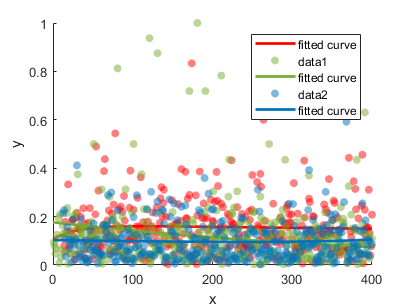

figure
maxValue = [max(MeanSpikesDEV) max(MeanSpikesCTR) max(MeanSpikesSTD)];

maxspikesValue = max(maxValue);

NormMeanSpikesDEV = MeanSpikesDEV./maxspikesValue;

scatter(TotalTrialsDEV,NormMeanSpikesDEV,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
hold on

f_DEV = fit(TotalTrialsDEV,NormMeanSpikesDEV,'exp2');
fp_DEV = plot(f_DEV);
set(fp_DEV, 'Color',[1 0 0],LineWidth=2);

NormMeanSpikesCTR = MeanSpikesCTR./maxspikesValue;

scatter(TotalTrialsCTR,NormMeanSpikesCTR,'filled','MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerFaceAlpha',.5)

f_CTR = fit(TotalTrialsCTR,NormMeanSpikesCTR,'exp2');
fp_CTR = plot(f_CTR);
set(fp_CTR, 'Color',[0.4660 0.6740 0.1880],LineWidth=2);


NormMeanSpikesSTD = MeanSpikesSTD./maxspikesValue;

scatter(TotalTrialsSTD,NormMeanSpikesSTD,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)

f_STD = fit(TotalTrialsSTD,NormMeanSpikesSTD,'exp2');
fp_STD = plot(f_STD);
set(fp_STD, 'Color',[0 0.4470 0.7410],LineWidth=2);

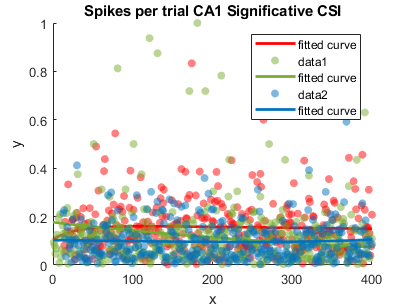

figure

scatter(TotalTrialsDEV,NormMeanSpikesDEV,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
hold on

f_DEV = fit(TotalTrialsDEV,NormMeanSpikesDEV,'exp2');
fp_DEV = plot(f_DEV);
set(fp_DEV, 'Color',[1 0 0],LineWidth=2);

scatter(TotalTrialsCTR,NormMeanSpikesCTR,'filled','MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerFaceAlpha',.5)

f_CTR = fit(TotalTrialsCTR,NormMeanSpikesCTR,'exp2');
fp_CTR = plot(f_CTR);
set(fp_CTR, 'Color',[0.4660 0.6740 0.1880],LineWidth=2);

scatter(TotalTrialsSTD,NormMeanSpikesSTD,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)

f_STD = fit(TotalTrialsSTD,NormMeanSpikesSTD,'exp2');
fp_STD = plot(f_STD);
set(fp_STD, 'Color',[0 0.4470 0.7410],LineWidth=2);
title('Spikes per trial CA1 Significative CSI')
ylim([0 1])

cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Spikes per trial';
saveas(gcf,'CA1_Significative CSI_SpkPerTrial.pdf');
saveas(gcf,'CA1_Significative CSI_SpkPerTrial.tif');
saveas(gcf,'CA1_Significative CSI_SpkPerTrial.fig');
saveas(gcf,'CA1_Significative CSI_SpkPerTrial.eps');

% % for n = 2:2:size(CTRTrialsFinal,2)
% %     for m = 1:2:size(CTRTrialsFinal,2)
% %         figure
% %         scatter(STDTrialsFinal(:,m),STDTrialsFinal(:,n),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5);
% %         hold on
% %         scatter(DEVTrialsFinal(:,m),DEVTrialsFinal(:,n),'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5);
% %         scatter(CTRTrialsFinal(:,m),CTRTrialsFinal(:,n),'filled','MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerFaceAlpha',.5);
% %         
% %         p = polyfit(STDTrialsFinal(:,m),STDTrialsFinal(:,n), 2);
% %         px = [min(STDTrialsFinal(:,m)) max(STDTrialsFinal(:,m))];
% %         py = polyval(p, px);
% %         plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);
% %         
% %         p = polyfit(CTRTrialsFinal(:,m),CTRTrialsFinal(:,n), 2);
% %         px = [min(CTRTrialsFinal(:,m)) max(CTRTrialsFinal(:,m))];
% %         py = polyval(p, px);
% %         plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);
% %         
% %         p = polyfit(DEVTrialsFinal(:,m),DEVTrialsFinal(:,n), 2);
% %         px = [min(DEVTrialsFinal(:,m)) max(DEVTrialsFinal(:,m))];
% %         py = polyval(p, px);
% %         plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);
% % 
% %     cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Spikes per trial'
% %     str_saveasPDF = sprintf('CSI_CA1%d.pdf', n);
% %     str_saveasTIF = sprintf('CSI_CA1%d.tif', n);
% %     str_saveasFIG = sprintf('CSI_CA1%d.fig', n);
% %     saveas(figure(1), str_saveas, 'fig');
% %     saveas(gcf,str_saveasPDF);
% %     saveas(gcf,str_saveasTIF);
% %     saveas(gcf,str_saveasFIG);
% % 
% %     hold off
% %     end
% % end